# Sensor data Acquisition from iOS Device

#### Objective

In this MATLAB script we will learn to:

- Connect desktop MATLAB to iOS/Android device using MATLAB Mobile

- Acquire sensor data from mobile

- Plot the sensor values over time

#### Connection to mobile device

- Install MATLAB support package for ios sensors

- Install MATLAB mobile on phone

- Sign in with the same account on MATLAB desktop and MATLAB Mobile

- Configure MATLAB Mobile to connect with your computer  [Follow these steps to connect MATLAB Mobile on your iOS device to MATLAB](matlab:web('https://www.mathworks.com/help/matlabmobile/ug/configure-matlab-mobile-for-desktop-connections.html', '-browser'))

- In desktop MATLAB define MOBILEDEV object 

close all
clear

iOSDevice = mobiledev

iOSDevice = mobiledev with properties:

                      Device: 'iPhone - iPhone'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions

#### Enabling and Tuning parameters

- Set a sample rate

- Enable sensor data streaming

- Set loggingTime

iOSDevice.SampleRate = 100

iOSDevice = mobiledev with properties:

                      Device: 'iPhone - iPhone'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions

iOSDevice.AngularVelocitySensorEnabled = 1

iOSDevice = mobiledev with properties:

                      Device: 'iPhone - iPhone'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions

iOSDevice.OrientationSensorEnabled = 1

iOSDevice = mobiledev with properties:

                      Device: 'iPhone - iPhone'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions

iOSDevice.AccelerationSensorEnabled = 1

iOSDevice = mobiledev with properties:

                      Device: 'iPhone - iPhone'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions

loggingTime = 10 % seconds

loggingTime = 10

- Enable logging

- Log 'loggingTime' seconds of phone sensor data 

- Log Acceleration, Angular Velocity and Orientation data from device

iOSDevice.Logging = 1

iOSDevice = mobiledev with properties:

                      Device: 'iPhone - iPhone'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 1
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Current Sensor Values:
                Acceleration: [0x3 double] (Waiting for data)
             AngularVelocity: [0x3 double] (Waiting for data)
                 Orientation: [0x3 double] (Waiting for data)

Supported functions

#### Visualizing Acceleration over time

- Plot Acceleration on xyz-axes over Time

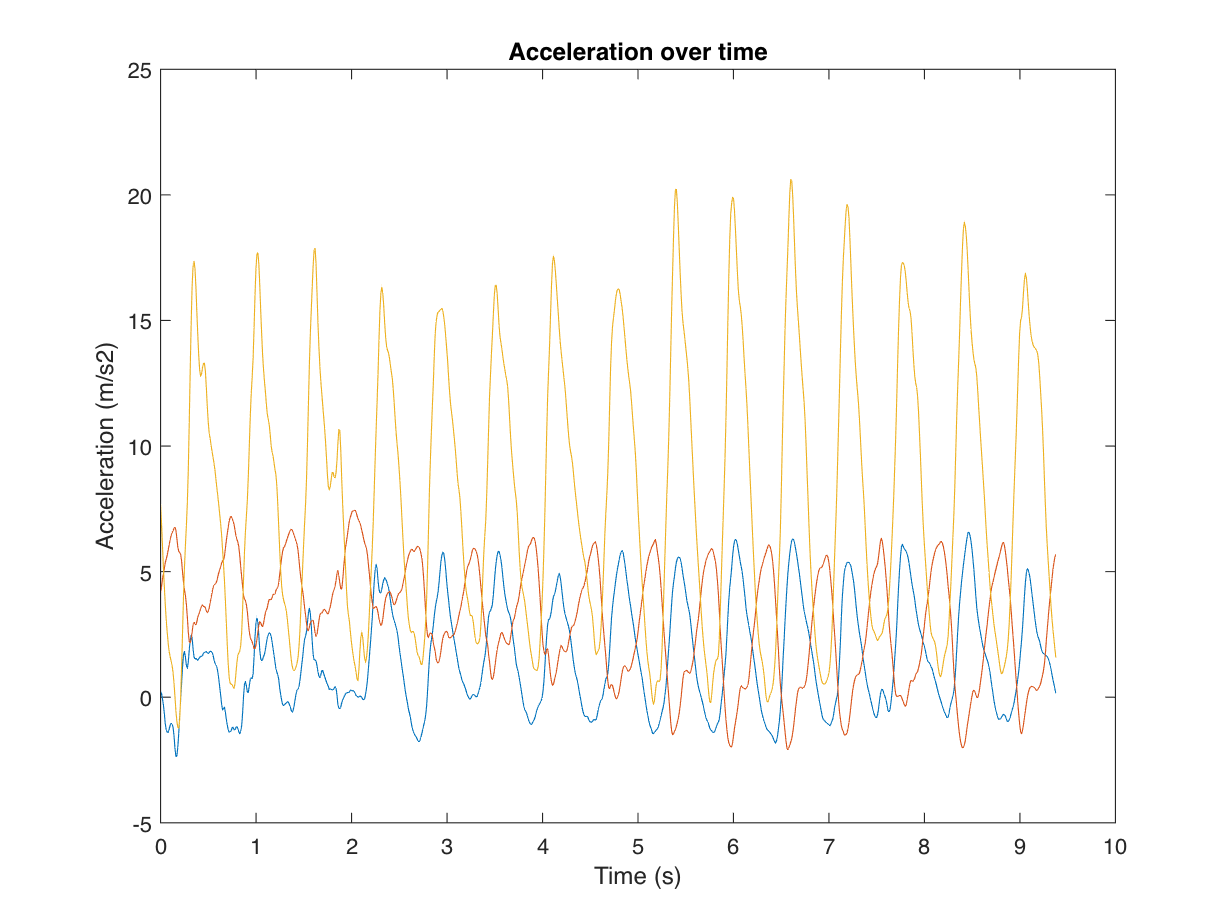

pause(loggingTime); 
[a, ta] = accellog(iOSDevice);
plot(ta, a)
title('Acceleration over time')
xlabel('Time (s)')
ylabel('Acceleration (m/s2)')

#### Visualizing Angular Velocity over time

- Plot Angular Velocity in xyz-zxes over time

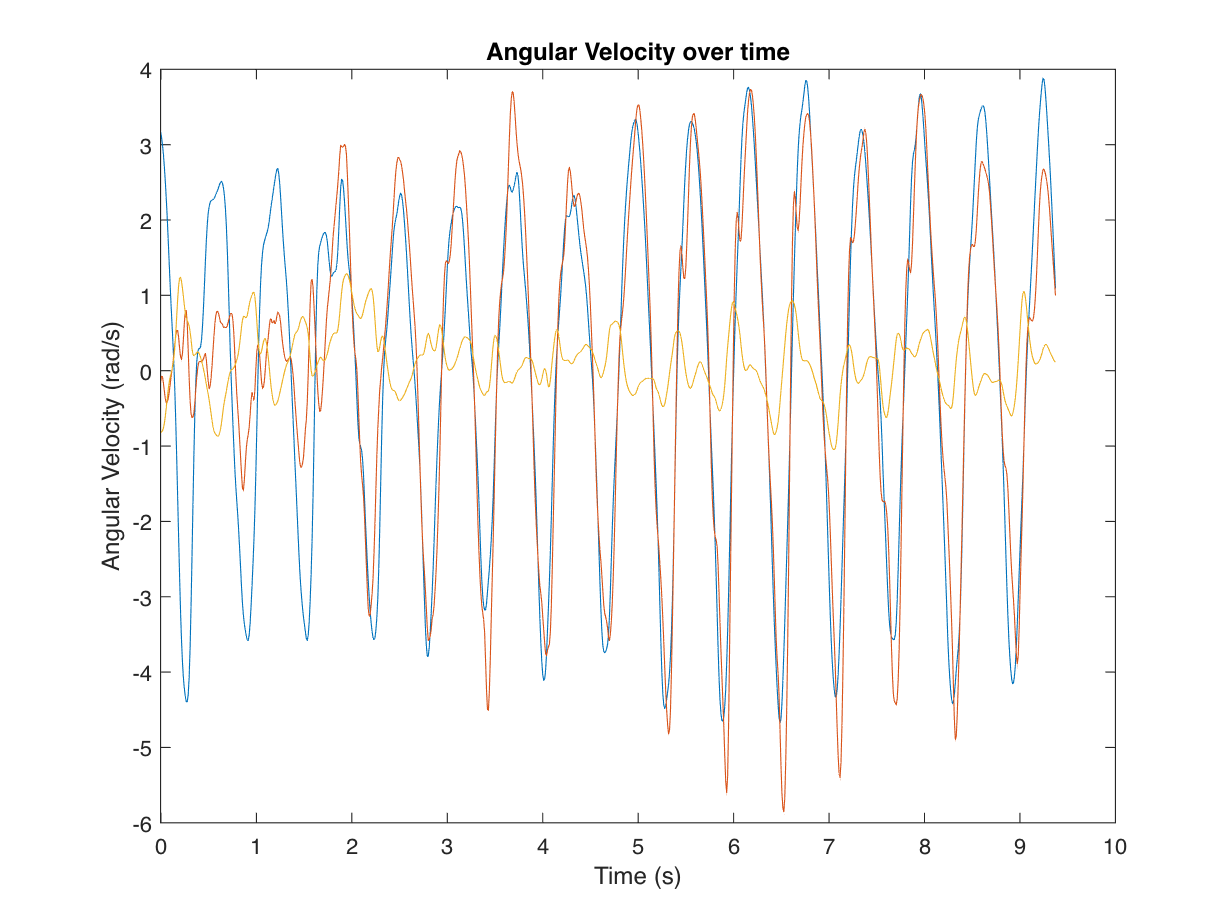

[w, tw] = angvellog(iOSDevice);
plot(tw, w)
title('Angular Velocity over time')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')

#### Visualizing Orientation over time

- Plot the Orientation in xyz-axes over time

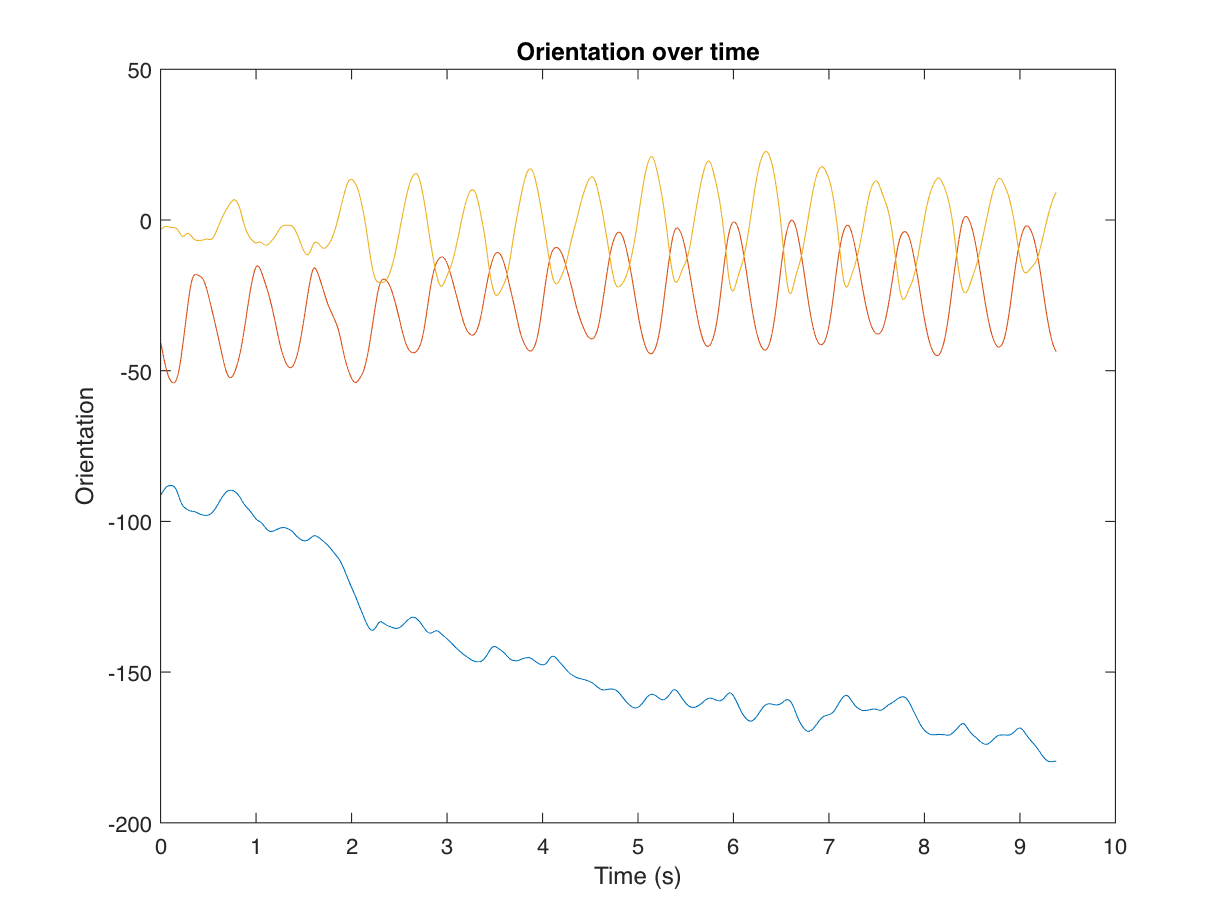

[oin, to] = orientlog(iOSDevice);
plot(to, oin)
title('Orientation over time')
xlabel('Time (s)')
ylabel('Orientation')

- Stop logging

iOSDevice.Logging = 0;